# Actividad 1 (Velocidades Lineales y angulares) Robot Planar 3GDL

Elaborado por: Marcos Allen Martínez Cortés   |   A01737939

Para obtener el vector de velocidades linear y angular para la configuración de un robot planar de 3GDL (grados de libertad), como el que se muestra en la imagen a continuación, primero tenemos que analizarlo.

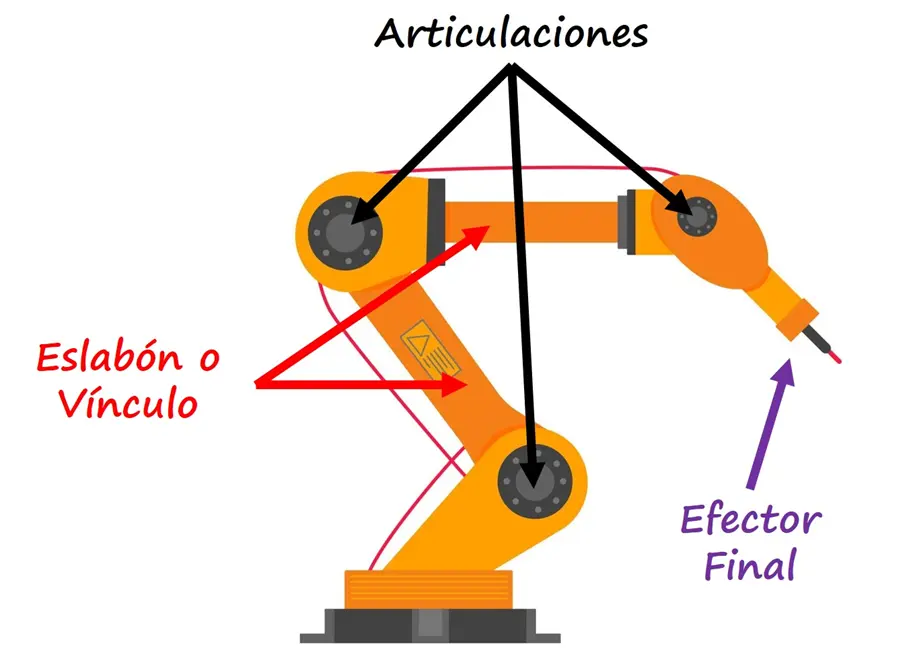

Imagen de: [https://makeblock.com.ar/wp-content/uploads/que-son-los-eslabones-y-articulaciones.webp](https://makeblock.com.ar/wp-content/uploads/que-son-los-eslabones-y-articulaciones.webp)

Dicho robot está conformado por tres articulaciones rotacionales. El sistema de referencia fijo (Xo, Yo, Zo) se coloca en la base del robot, de tal manera que el eje Zo es perpendicular al plano de la imagen.

Para poder obtener la velocidad lineal y angular aplicaremos la cinemática diferencial, cuyo objetivo es establecer las relaciones entre las velocidades de las articulaciones y las velocidades lineares y angulares del efector final.

De este modo, para realizarlo en MATLAB empezaremos por limpiar el espacio de trabajo (y adicionales).

% Limpieza de pantalla
clear all
close all
clc

### **SECCIÓN 1**

Procederemos a declarar las variables simbólicas a utilizar, que incluyen:

- Las funciones theta con respecto al tiempo -th(t)- para las tres juntas, esto para la rotación de cada junta.

- t para el tiempo.

- Las tres l, que son las longitudes de los eslabones.

Variables de entrada: ninguna.

Variables de salida: variables simbólicas (th1(t), th2(t), th3(t), t, l1, l2, l3).

%SECCIÓN 1
% Declaración de variables simbólicas
syms th1(t) th2(t) th3(t) t l1 l2 l3
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

### **SECCIÓN 2**

Adicionalmente, también es necesario establecer la configuración del robot, considerando si las juntas son rotacionales o prismáticas.

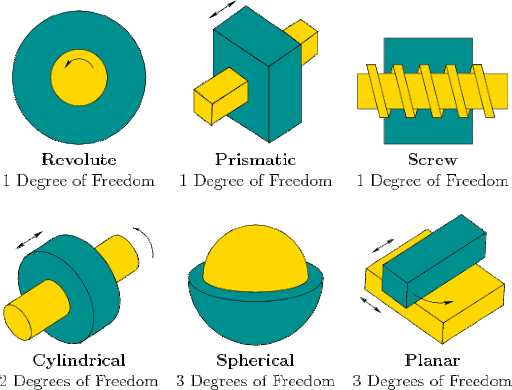

Imagen de: [https://encrypted-tbn0.gstatic.com/images?q=tbn:ANd9GcRV4iX26CWioV6KqOKe7ApSo0ivnPhRJpvucw&s](https://encrypted-tbn0.gstatic.com/images?q=tbn:ANd9GcRV4iX26CWioV6KqOKe7ApSo0ivnPhRJpvucw&s)

En este caso, para el robot planar las tres juntas son rotacionales.

Variables de entrada: ninguna.

Variables de salida: vector RP.

%SECCIÓN 2
% Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP = [0 0 0];
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

### **SECCIÓN 3**

Posteriormente, tenemos que crear el vector de coordenadas articulares; con un elemento por cada articulación/junta. Este es para definir la configuración del robot mediante los ángulos (para articulaciones rotacionales) de cada articulación, indicando su posición.

Variables de entrada: variables simbólicas th1, th2 y th3.

Variables de salida: vector Q.

%SECCIÓN 3
% Creamos el vector de coordenadas articulares
Q = [th1, th2, th3];
disp('Coordenadas generalizadas');

Coordenadas generalizadas


pretty(Q);

(th1(t), th2(t), th3(t))



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

### SECCIÓN 4

Y obtendremos el vector de velocidades generalizadas, creándolo con la derivada del vector de coordenadas. Esto, ya que la derivada de la posición con respecto al tiempo es la velocidad.

Variables de entrada: vector Q y variable simbólica t.

Variables de salida: vector Qp.

% Creamos el vector de velocidades generalizadas
Qp = diff(Q, t);
disp('Velocidades generalizadas');

Velocidades generalizadas


pretty(Qp);

/  d          d          d        \
| -- th1(t), -- th2(t), -- th3(t) |
\ dt         dt         dt        /



**SECCIÓN 5**

Adicionalmente, estableceremos (con respecto a la cantidad de juntas utilizando la función size con el parámetro 2 para dimensión en columnas) la variable de grados de libertad que será utilizada más adelante, tanto en formato numérico como en string.

Variables de entrada: vector RP.

Variables de salida: variables GDL (double) y GSL_str (string).

%SECCIÓN 5
% Número de grado de libertad del robot
GDL = size(RP,2);
GDL_str = num2str(GDL); % Convertir a string
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

### SECCIÓN 6

Para continuar, necesitamos obtener el vector de posición de la junta 1 respecto a 0 (sistema de referencia). Como se estableció, el sistema de referencia fijo (Xo, Yo, Zo) se coloca en la base del robot, de tal manera que el eje Zo es perpendicular al plano de la imagen.

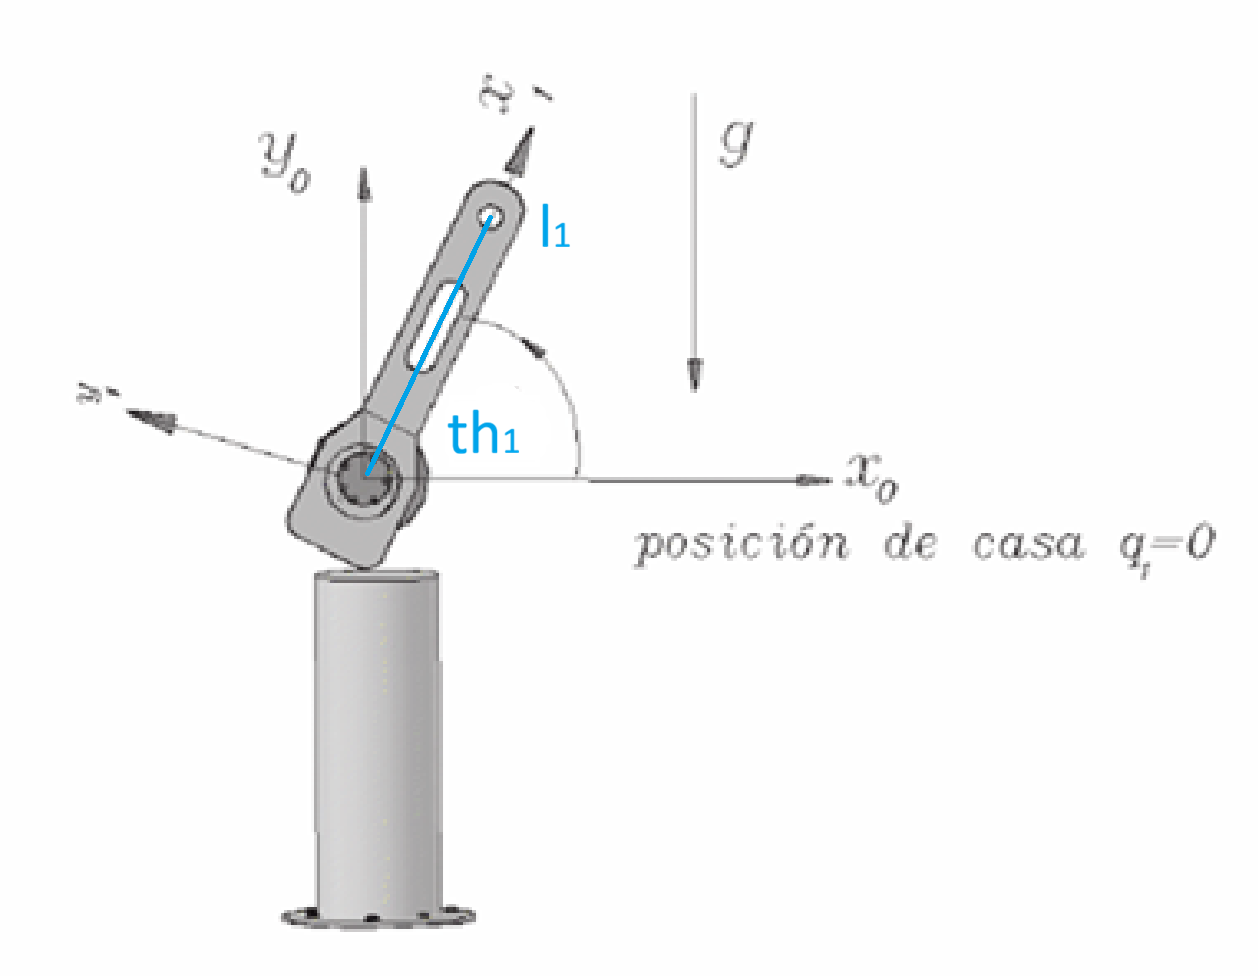

De esta forma, podemos utilizar las funciones trigonométricas para obtener la posición de la junta 1 respecto a 0 (sistema de referencia).

- l1 es la longitud del primer eslabón.

- theta1 es el ángulo respecto al eje x del sistema base (x0).

De esta manera, podemos utilizar seno y coseno para expresar la posición y crear el vector de posición o vector de traslación. Además, z es 0 debido a que se trata de un robot planar.

%SECCIÓN 6
% Junta 1
% Posición de la junta 1 respecto a 0
P(:,:,1) = [l1*cos(th1); l1*sin(th1); 0];

Adicionalmente, utilizaremos la matriz de rotación, que representa la rotación de theta grados del plano en sentido antihorario.

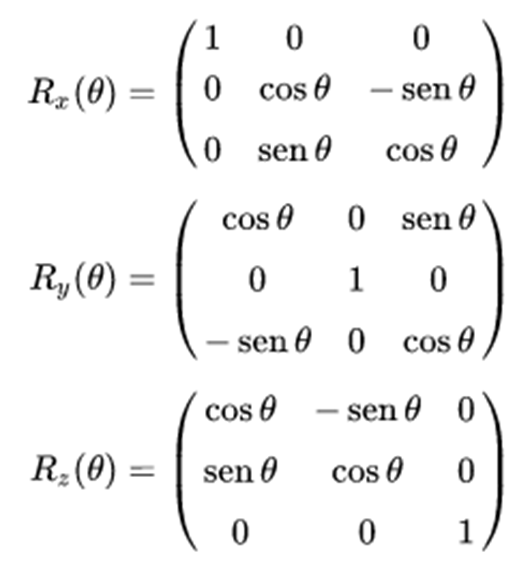

En este caso, la rotación es alrededor del eje Z, ya que es el eje que permanece fijo (z0 = z1). Entonces, para la matriz de rotación de la junta 1 respecto a 0, utilizaremos la matriz de rotación alrededor de Z.

% Matriz de rotación de la junta 1 respecto a 0
R(:,:,1) = [cos(th1) -sin(th1) 0;
            sin(th1)  cos(th1) 0;
            0         0        1];

Para la junta 2 y tres realizaremos lo mismo; con diferencia de que el vector de posición/traslación y la matriz de rotación de la junta 2 es respecto a la 1, y para la 3 es respecto a la 2.

% Junta 2
% Posición de la junta 2 respecto a 1
P(:,:,2) = [l2*cos(th2); l2*sin(th2); 0];
% Matriz de rotación de la junta 2 respecto a 1
R(:,:,2) = [cos(th2) -sin(th2) 0;
            sin(th2)  cos(th2) 0;
            0         0        1];

% Junta 3
% Posición de la junta 3 respecto a 2
P(:,:,3) = [l3*cos(th3); l3*sin(th3); 0];
% Matriz de rotación de la junta 3 respecto a 2
R(:,:,3) = [cos(th3) -sin(th3) 0;
            sin(th3)  cos(th3) 0;
            0         0        1];
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Variables de entrada: variables simbólicas th1, th2, th3, l1, l2 y l3.

Variables de salida: arreglos multidimensionales (3D) P y R, que representan la posición y la rotación de las 3 juntas.

### SECCIÓN 7

Adicionalmente, crearemos un vector de ceros, que utilizaremos para la matriz de transformación homogénea.

% Creamos un vector de ceros
Vector_Zeros = zeros(1, 3);

Con lo realizado, podemos crear las matrices de transformación homogénea para cada una de las juntas.

La matriz de transformación homogénea relaciona dos sistemas de coordenadas y se define mediante la transformación canónica establecida por los parámetros Denavit-Hartenberg.

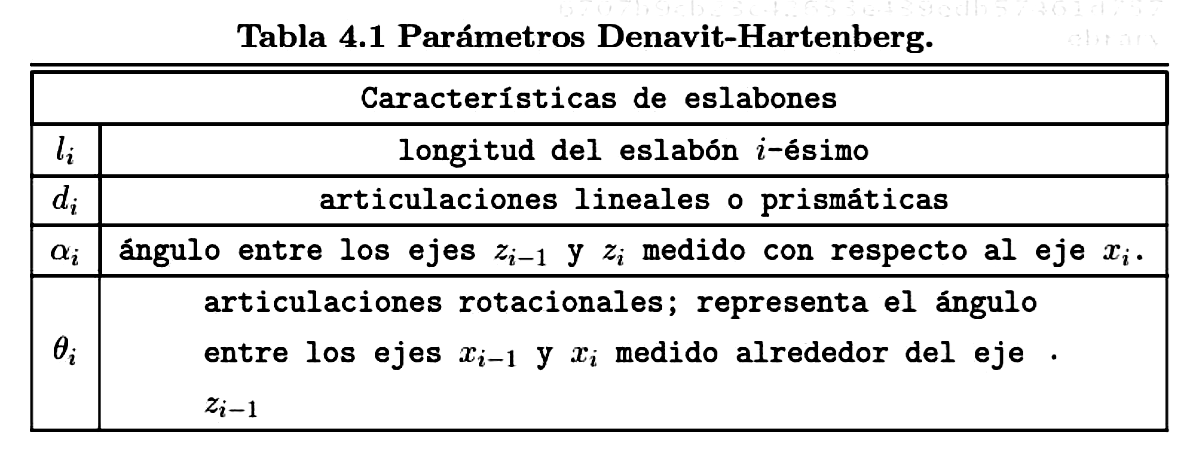

De este modo, la matriz de transformación homogénea se constituye de la siguiente manera:

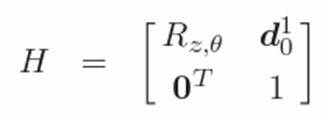

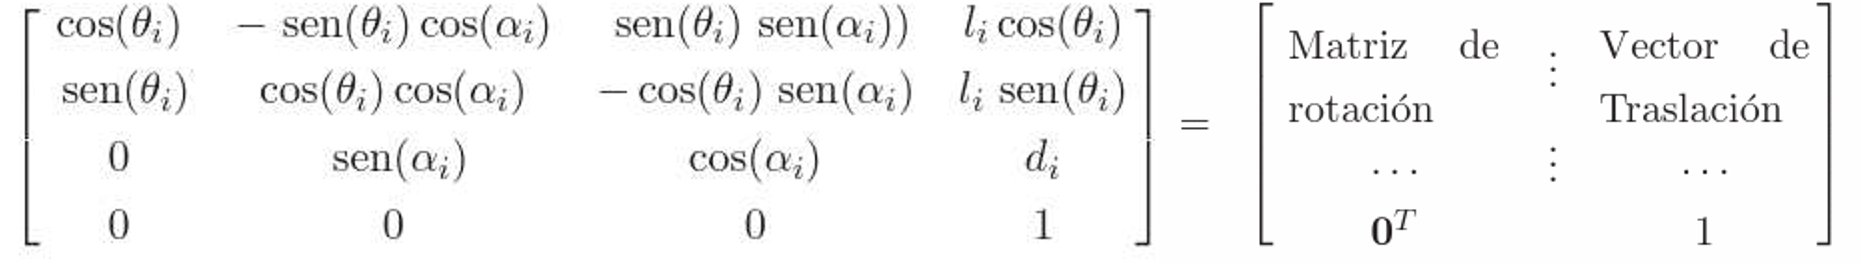

Para esto, comenzaremos por inicializar las matrices de transformación homogénea tanto locales como globales. Y, también inicializaremos las posiciones (vectores de traslación) y las matrices de rotación (junto con sus inversas) vistas desde el marco de referencia inercial.

Un marco de referencia inercial es un marco de referencia en el que un objeto permanece en reposo o con una velocidad constante a menos que otra fuerza actúe sobre él.

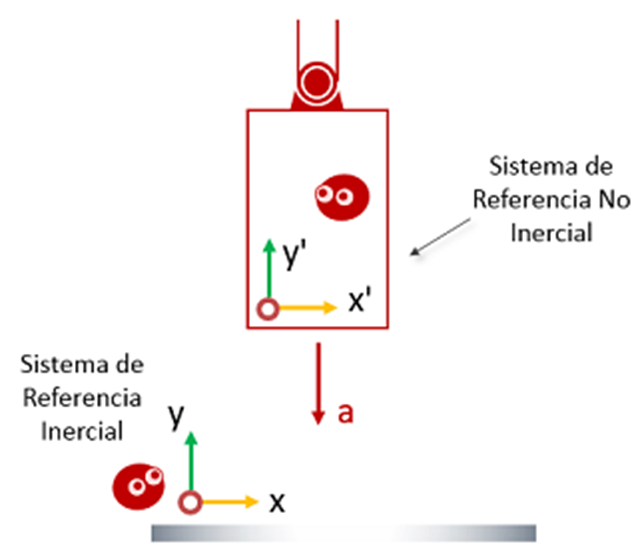

% Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL) = simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
% Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL) = simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
% Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL) = P(:,:,GDL);
% Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL) = R(:,:,GDL);
% Inicializamos las INVERSAS de las matrices de rotación vistas desde el marco de referencia inercial
RO_inv(:,:,GDL) = R(:,:,GDL);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Variables de entrada: arreglos multidimensionales R y P.

Variables de salida: vector de ceros, y arreglos multidimensionales inicializados (A, T, PO, RO y RO_inv).

### SECCIÓN 8

A continuación, dentro del ciclo for recorremos cada grado de libertad; es decir, cada junta.

Primero construimos la matriz de transformación homogénea local (A), tal como se explicó previamente, esto para poder construir la global (T).

Después, las multiplica acumulativamente para ir construyendo la matriz global (T). Es decir, T1 queda de la misma manera (A1), la T2 es A1*A2, y la T3 es T2*A3 = A1*A2*A3.

Esto construye la matriz de transformación global.

Al final se extraen las posiciones (vectores de traslación) y las matrices de rotación (junto con su inversa) de la matriz de transformación global; es decir, descomponemos la matriz de transformación global para obtener dichos datos desde el sistema de referencia inercial; o de otra forma, la matriz de tranformación global permite analizar el comportamiento del efector final desde el marco de referencia.

El try-catch en el ciclo for permite que en la primera iteración la matriz global se quede con el valor de la matriz local, ya que al ser la primera todavía no hay un acumulado de la multiplicación acumulativa.

%SECCIÓN 8
for i = 1:GDL
    i_str= num2str(i);
    
    % Locales
    disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i) = simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
    pretty(A(:,:,i));
    
    % Globales
    try
        T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
        T(:,:,i)= A(:,:,i);
    end
    disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i)= simplify(T(:,:,i));
    pretty(T(:,:,i))

    RO(:,:,i)= T(1:3,1:3,i);
    RO_inv(:,:,i)= transpose(RO(:,:,i));
    PO(:,:,i)= T(1:3,4,i);
    %pretty(RO(:,:,i));
    %pretty(RO_inv(:,:,i));
    %pretty(PO(:,:,i));
end

Matriz de Transformación local A1


/ cos(th1(t)), -sin(th1(t)), 0, l1 cos(th1(t)) \
|                                              |
| sin(th1(t)),  cos(th1(t)), 0, l1 sin(th1(t)) |
|                                              |
|      0,            0,      1,        0       |
|                                              |
\      0,            0,      0,        1       /



Matriz de Transformación global T1


/ cos(th1(t)), -sin(th1(t)), 0, l1 cos(th1(t)) \
|                                              |
| sin(th1(t)),  cos(th1(t)), 0, l1 sin(th1(t)) |
|                                              |
|      0,            0,      1,        0       |
|                                              |
\      0,            0,      0,        1       /



Matriz de Transformación local A2


/ cos(th2(t)), -sin(th2(t)), 0, l2 cos(th2(t)) \
|                                              |
| sin(th2(t)),  cos(th2(t)), 0, l2 sin(th2(t)) |
|                                              |
|      0,            0,      1,        0       |
|                                              |
\      0,            0,      0,        1       /



Matriz de Transformación global T2


/ #2, -#1, 0, l1 cos(th1(t)) + l2 #2 \
|                                    |
| #1,  #2, 0, l1 sin(th1(t)) + l2 #1 |
|                                    |
|  0,  0,  1,            0           |
|                                    |
\  0,  0,  0,            1           /

where

   #1 == sin(th1(t) + th2(t))

   #2 == cos(th1(t) + th2(t))




Matriz de Transformación local A3


/ cos(th3(t)), -sin(th3(t)), 0, l3 cos(th3(t)) \
|                                              |
| sin(th3(t)),  cos(th3(t)), 0, l3 sin(th3(t)) |
|                                              |
|      0,            0,      1,        0       |
|                                              |
\      0,            0,      0,        1       /



Matriz de Transformación global T3


/ #2, -#1, 0, l1 cos(th1(t)) + l3 #2 + l2 cos(th1(t) + th2(t)) \
|                                                              |
| #1,  #2, 0, l1 sin(th1(t)) + l3 #1 + l2 sin(th1(t) + th2(t)) |
|                                                              |
|  0,  0,  1,                         0                        |
|                                                              |
\  0,  0,  0,                         1                        /

where

   #1 == sin(th1(t) + th2(t) + th3(t))

   #2 == cos(th1(t) + th2(t) + th3(t))





%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Calculamos la matriz de transformación del marco de referencia inercial
% visto desde el actuador final
% disp(strcat('Matriz de Transformación T', GDL_str,'_O calculada de forma manual'));
% RF_O=RO_inv(:,:,GDL);
% PF_O=-RF_O*PO(:,:,GDL);
% TF_O= simplify([RF_O PF_O; Vector_Zeros 1]);
% pretty(TF_O);

% disp(strcat('Matriz de Transformación T', GDL_str,'_O calculada de forma automática'));
% pretty(simplify(inv(T(:,:,GDL))));

Variables de entrada: variable GDL, vector de ceros y arreglos multidimensionales inicializados (A, T, PO, RO y RO_inv).

Variables de salida: arreglos multidimensionales con valores (A, T, PO, RO y RO_inv).

### SECCIÓN 9

Con esto, tendremos que construir el Jacobiano, que establece la relación entre las velocidades articulares y la velocidad linear y angular en el extremo el efector final del robot, expresadas en el sistema inercial del robot. Es decir, sabiendo que tan rápido se mueven las articulaciones (juntas) del robot, podemos conocer qué tan rápido se mueve y rota el efector final respecto al sistema de referencia.

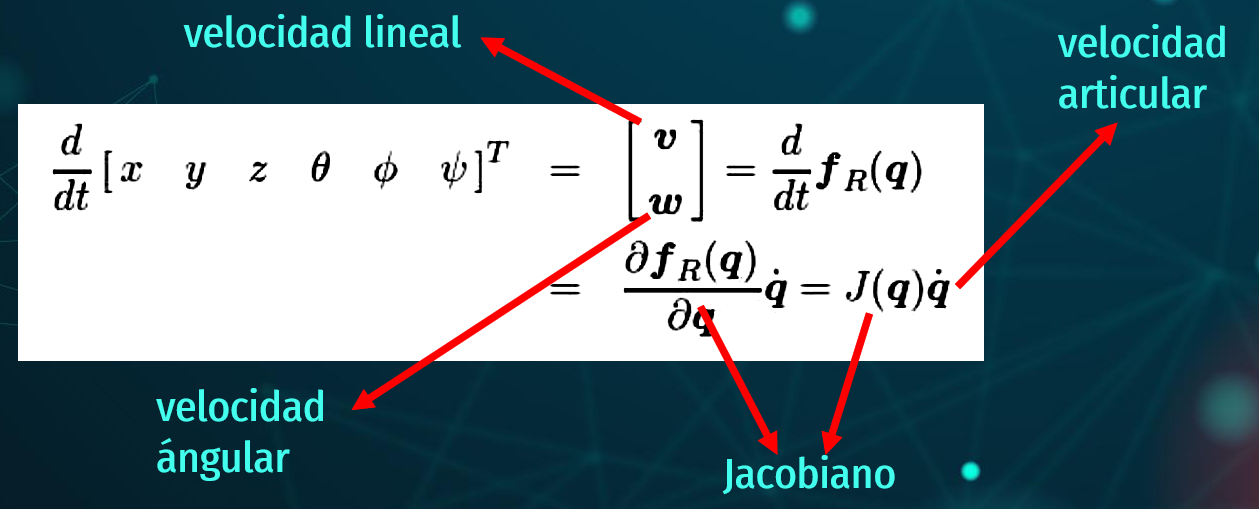

Primero lo haremos de forma diferencial, calculando primero el Jacobiano lineal a través de las derivadas parciales de las posiciones en x, en y, y en z respecto a th1, th2 y th3; para unirlas como se muestra en la imagen y crear la matriz del Jacobiano lineal.

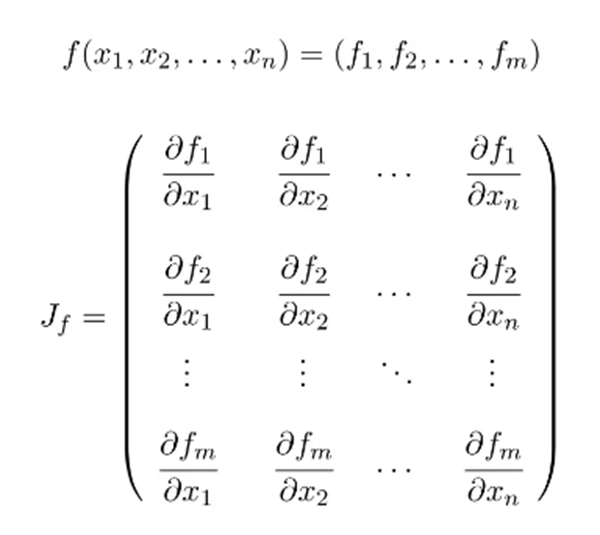

%SECCIÓN 9
% Calculamos el jacobiano lineal de forma diferencial
disp('Jacobiano lineal obtenido de forma diferencial');

Jacobiano lineal obtenido de forma diferencial


% Derivadas parciales de x respecto a th1, th2 y th3
Jv11 = functionalDerivative(PO(1,1,GDL), th1);
Jv12 = functionalDerivative(PO(1,1,GDL), th2);
Jv13 = functionalDerivative(PO(1,1,GDL), th3);
% Derivadas parciales de y respecto a th1, th2 y th3
Jv21 = functionalDerivative(PO(2,1,GDL), th1);
Jv22 = functionalDerivative(PO(2,1,GDL), th2);
Jv23 = functionalDerivative(PO(2,1,GDL), th3);
% Derivadas parciales de z respecto a th1, th2 y th3
Jv31 = functionalDerivative(PO(3,1,GDL), th1);
Jv32 = functionalDerivative(PO(3,1,GDL), th2);
Jv33 = functionalDerivative(PO(3,1,GDL), th3);

% Creamos la matriz del Jacobiano lineal
jv_d = simplify([Jv11 Jv12 Jv13;
                 Jv21 Jv22 Jv23;
                 Jv31 Jv32 Jv33]);
pretty(jv_d);

/ - l1 sin(th1(t)) - #1 - l2 sin(th1(t) + th2(t)), - #1 - l2 sin(th1(t) + th2(t)), -#1 \
|                                                                                      |
|  l1 cos(th1(t)) + #2 + l2 cos(th1(t) + th2(t)),   #2 + l2 cos(th1(t) + th2(t)),   #2 |
|                                                                                      |
\                        0,                                       0,                0  /

where

   #1 == l3 sin(th1(t) + th2(t) + th3(t))

   #2 == l3 cos(th1(t) + th2(t) + th3(t))




%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Variables de entrada: arreglo multidimensional PO, variable GDL y variables simbólicas th1, th2 y th3.

Variables de salida: variables Jv11, Jv12, Jv13, Jv21, Jv22, Jv23, Jv31, Jv32, Jv33 y matriz jv_d.

**SECCIÓN 10**

Continuamos calculando el Jacobiano ahora de forma analítica.

Inicializamos las variables y después en el ciclo for iteramos sobre todas las articulaciones.

Aquí tenemos dos casos según el tipo de articulación, aunque en este caso, las tres articulaciones o juntas son rotacionales.

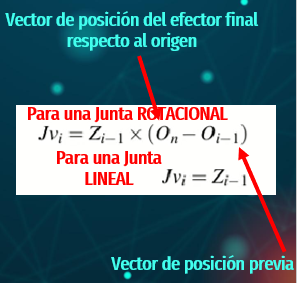                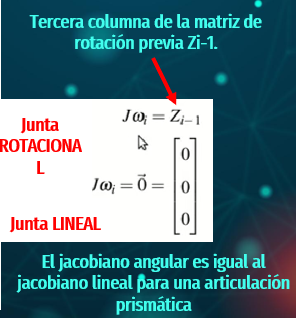

Lo que hace en el caso de las juntas rotacionales es:

- Para la parte lineal, se calcula el producto cruz entre el eje Z anterior (eje de rotación) y el vector de posición del efector final menos el vector de posición previo; esto representa la velocidad lineal inducida por una rotación, ya que cuando hay un movimiento circular, la velocidad lineal es tangencial a esa trayectoria. Además, en el try-catch incluido para la el Jacobiano lineal, se realiza el producto cruz respecto al vector [0 0 1] en lugar de la matriz de rotación; esto debido a que en la primera iteración no hay una matriz previa, por lo que se asume el eje base Z.

- Para la parte angular, es el eje Z de la articulación anterior, ya que la rotación se produce alrededor de ese eje. Además, se incluye un try-catch para la primera rotación, ya que como no hay un sistema que le anteceda, ese sistema anterior de representa por el vector [0, 0, 1] que sería el eje base Z.

Lo que haría en el caso de las juntas prismáticas (dado que no aplica para el robot planar analizado) es:

- Para la parte lineal, utiliza el eje Z de la matriz de rotación del sistema anterior, esto debido a que una junta prismática produce movimiento lineal en la dirección del eje. Además, el try-catch incluido para el Jacobiano lineal utiliza el vector [0, 0, 1] cuando no hay un sistema que le anteceda, tomando como base el eje Z.

- Para la parte angular se queda en cero, ya que como no hay rotación, no se produce velocidad angular.

%SECCIÓN 10
% Calculamos el jacobiano lineal de forma analítica
Jv_a(:,GDL) = PO(:,:,GDL);
Jw_a(:,GDL) = PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 %Casos: articulación rotacional
        %Para las juntas de revolución
        try
            Jv_a(:,k) = cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k) = RO(:,3,k-1);
        catch
            Jv_a(:,k) = cross([0,0,1], PO(:,:,GDL));
            Jw_a(:,k) = [0,0,1];
        end
    %Para las juntas prismáticas
    elseif RP(k)==1 %Casos: articulación prismática
    %
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
    end
end

Finalmente, simplificamos los Jacobianos obtenidos de forma analítica. Y calculamos las velocidades lineales y angulares mediante el Jacobiano lineal y angular, utilizando el vector de velocidades articulares generalizadas.

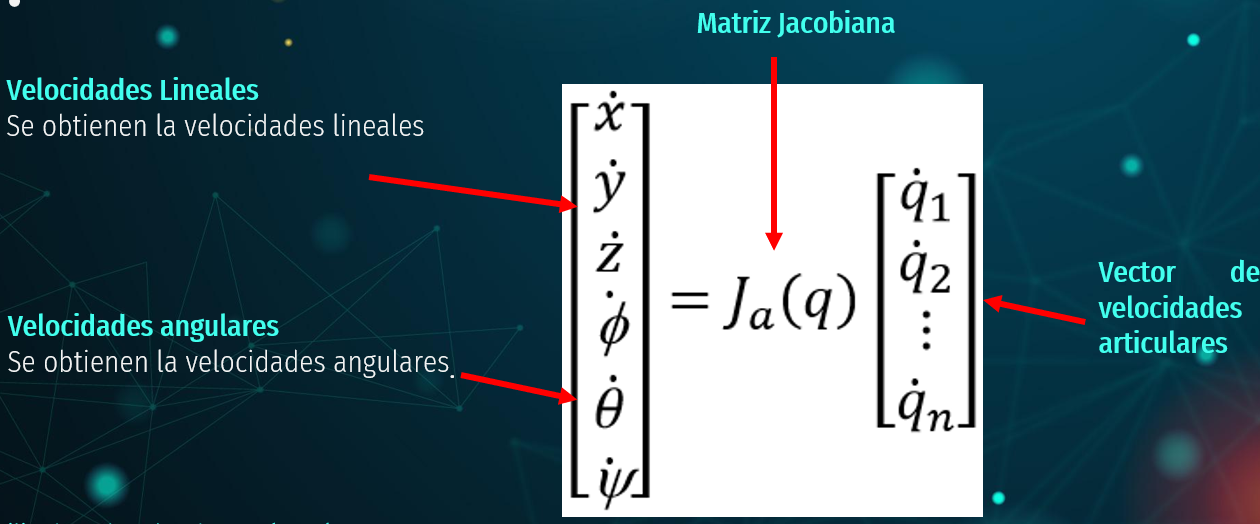

Jv_a = simplify (Jv_a);
Jw_a = simplify (Jw_a);
disp('Jacobiano lineal obtenido de forma analítica');

Jacobiano lineal obtenido de forma analítica


pretty(Jv_a);

/ - l1 sin(th1(t)) - #1 - l2 sin(th1(t) + th2(t)), - #1 - l2 sin(th1(t) + th2(t)), -#1 \
|                                                                                      |
|  l1 cos(th1(t)) + #2 + l2 cos(th1(t) + th2(t)),   #2 + l2 cos(th1(t) + th2(t)),   #2 |
|                                                                                      |
\                        0,                                       0,                0  /

where

   #1 == l3 sin(th1(t) + th2(t) + th3(t))

   #2 == l3 cos(th1(t) + th2(t) + th3(t))




disp('Jacobiano ángular obtenido de forma analítica');

Jacobiano ángular obtenido de forma analítica


pretty(Jw_a);

/ 0, 0, 0 \
|         |
| 0, 0, 0 |
|         |
\ 1, 1, 1 /




disp('Velocidad lineal obtenida mediante el Jacobiano lineal');

Velocidad lineal obtenida mediante el Jacobiano lineal


V=simplify (Jv_a*Qp');
pretty(V);

/ - #4 (l3 sin(#1) + l2 sin(#2)) - #5 (l1 sin(th1(t)) + l3 sin(#1) + l2 sin(#2)) - l3 #3 sin(#1) \
|                                                                                                |
|  #4 (l3 cos(#1) + l2 cos(#2)) + #5 (l1 cos(th1(t)) + l3 cos(#1) + l2 cos(#2)) + l3 #3 cos(#1)  |
|                                                                                                |
\                                                0                                               /

where

   #1 == th1(t) + th2(t) + th3(t)

   #2 == th1(t) + th2(t)

         _________
          d
   #3 == -- th3(t)
         dt

         _________
          d
   #4 == -- th2(t)
         dt

         _________
          d
   #5 == -- th1(t)
         dt




disp('Velocidad angular obtenida mediante el Jacobiano angular');

Velocidad angular obtenida mediante el Jacobiano angular


W=simplify (Jw_a*Qp');
pretty(W);

/                 0                 \
|                                   |
|                 0                 |
|                                   |
| _________   _________   _________ |
|  d           d           d        |
| -- th1(t) + -- th2(t) + -- th3(t) |
\ dt          dt          dt        /




%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Variables de entrada: variable GDL, arreglos multidimensionales RO y PO, y vector Qp.

Variables de salida: matrices Jv_a, Jw_a, V y W.

Con esto podemos obtener la velocidad lineal y angular, cuya interpretación se encuentra a continuación.

- **Velocidad lineal**:

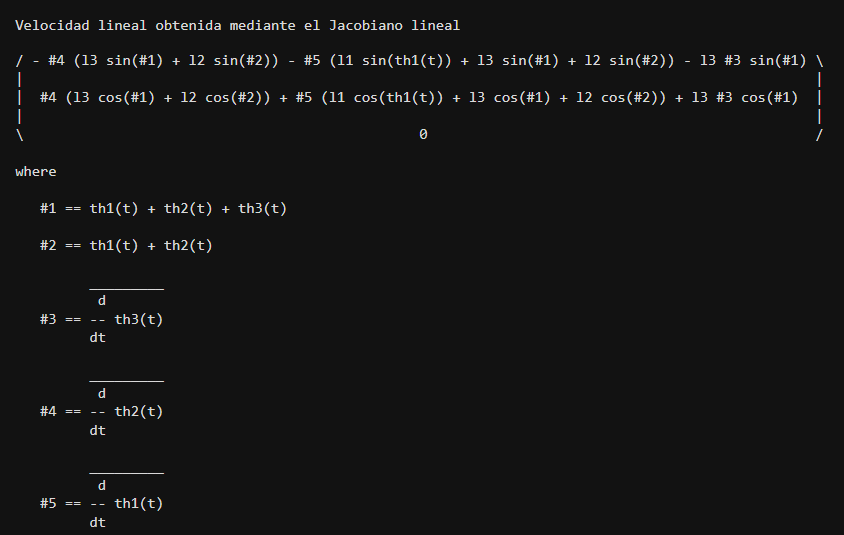

El tercer componente (Vz) es 0 ya que se trata de un robot planar, y al no haber movimiento sobre ese eje, la velocidad será cero.

Y, para Vx y Vy, podemos interpretarlos de forma que el efector se mueve en el plano XY y que la velocidad lineal del efector final está relacionada con las velocidades articulares en el espacio cartesiano; es decir, el Jacobiano nos permite conocer que la velocidad lineal del efector final depende de las longitudes de los eslabones y las posiciones/velocidades de las articulaciones.

- **Velocidad angular**:

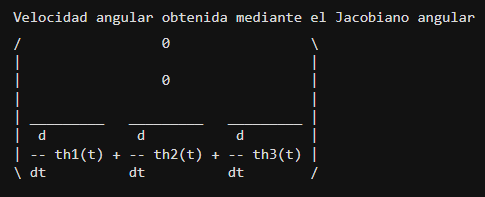

Para la velocidad angular, como todas las articulaciones (o juntas) rotan sobre el eje Z, no hay rotación sobre el eje X ni sobre el eje Y, por lo que tienen un valor de 0.

Y el efector rota sobre el eje Z con la suma de las velocidades angulares de todas las articulaciones.